# Proyecto Final: Moviles y Gravedad Sol Tierra y Venus

## **Algoritmos Numéricos por Computadora**

## Manuel Fernández 166496

## Bernardo Altamirano 167881

## Santiago Borobia 165323

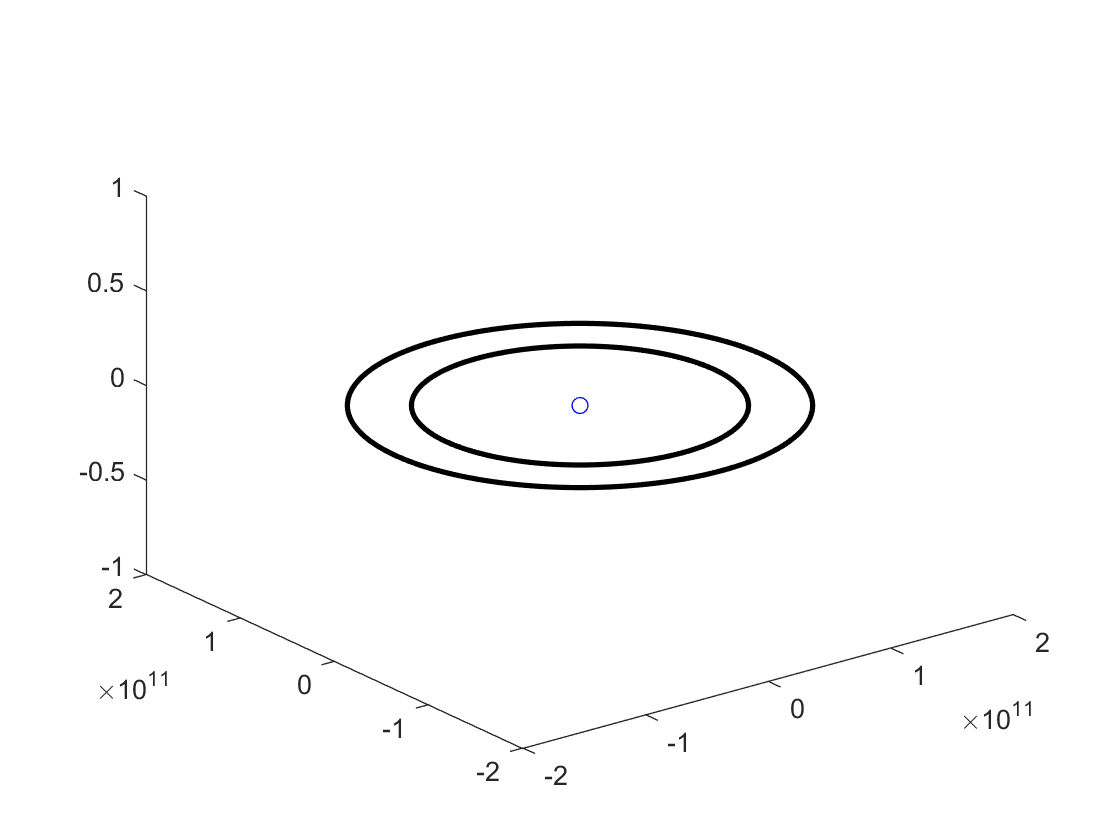

% Un satélite orbitando la Tierra
% La Tierra en el origen (inicialmente)
% El satélite tiene una masa de 20 toneladas 
% y se encuentra a 108 km de altura (eje x)
% Los vectores tienen los datos [Tierra, satélite]
  
% y  = [r;v] 
% y' = [v;a]
% dy/dt = f(t,y)

global G m;
G = 6.67408E-11;              % m3 kg-1 s-2
mS = 1.989e30;                % masa de Sol
mV = 4.867e24;                % masa de Venus
mT = 5.9736e24;               % masa de Tierra
m = [mS, mV, mT]; 

rS = 695.510e6;                     % radio del Sol m
hV = 108.2e9;                       % altura de la superficie del Sol a Venus        
hT = 149.6e9;                       % altura de la superficie del Sol a la Tierra


r0 = [ [0;0;0], [rS+hV;0;0], [rS+hT;0;0] ];      
                                    
vV = sqrt(G * m(1)/r0(1,2));
vT = sqrt(G * m(1)/r0(1,3));
v0 = [ [0;0;0], [0;vV;0], [0;vT;0] ];         

wV = vV/(rS+hV);
wT = vT/(rS+hT);

TV = (2*pi)/wV;  
TT = (2*pi)/wT; 

h = 600;                 
nv = 1;                 
NkV = nv*ceil(TV/h);
NkT = nv*ceil(TT/h); 

posV = zeros(6,NkV+1);    
posV(:,1) = [r0(:,1);r0(:,2)];
posT = zeros(6,NkT+1);    
posT(:,1) = [r0(:,1);r0(:,3)];

%Esto es un rk4 para Venus
y1 = [r0(1:end,1:2);v0(1:end,1:2)];
posV = rk4(y1, NkV, posV, h);

plot3(posV(1,:),posV(2,:),posV(3,:),'ob');
hold on;
plot3(posV(4,:),posV(5,:),posV(6,:),'.k');
grid minor;
hold on;

%Esto es un rk4 Tierra
y2 = [r0(:,[1,3]);v0(:,[1,3])];
posT = rk4(y2, NkT, posT, h);

plot3(posT(4,:),posT(5,:),posT(6,:),'.k');
grid minor;

function ydot = f(~,y)
  global G m;                 
  r = y(1:3,:);
  v = y(4:6,:);
  dr = r(:,2) - r(:,1);         
  u = dr / norm(dr);            
  dr2 = norm(dr)^2;         	 
  F = (G*m(1)*m(2)/dr2) * u;    
  a = [F/m(1), - F/m(2)];       
  ydot = [v;a];
end

function pos = rk4(y, Nk, pos, h)
    for t=2:Nk+1
      s1 = f(t,y);
      s2 = f(t+h/2,y+(h/2)*s1);
      s3 = f(t+h/2,y+(h/2)*s2);
      s4 = f(t+h, y+h*s3);
      slope = (s1+2*s2+2*s3+s4)/6;
      y = y + slope*h;
    
      r = y(1:3,:); 
      pos(:,t) = [r(:,1);r(:,2)];  
    end
end